# Solution to *Wright Flyer Wind Tunnel Test I* exercise

## 1. Load data

load wrightWindTunnel

## 2. Find mean and standard deviation

Verify they are reasonably consistent across the different tests.

meanFl = mean(lift);
stdFl = std(lift);
meanFd = mean(drag);
stdFd = std(drag);
disp('The mean and standard deviation of the lift force measurements are:')

The mean and standard deviation of the lift force measurements are:


disp([meanFl;stdFl])

  710.6582  713.1541  707.2143  719.0557  708.9484
  274.8647  264.8753  266.0181  276.0666  262.3681



disp('The mean and standard deviation of the drag force measurements are:')

The mean and standard deviation of the drag force measurements are:


disp([meanFd;stdFd])

  135.8427  136.5835  136.1740  136.9849  136.3786
   28.8205   29.5115   27.9271   30.0550   29.2138



## 3. Calculate coefficient of drag


$$C_D = \frac{F_D}{A \cdot P_d}$$


A = 510;
CD = drag./(A*Pd);

## 4. Plot drag coefficients

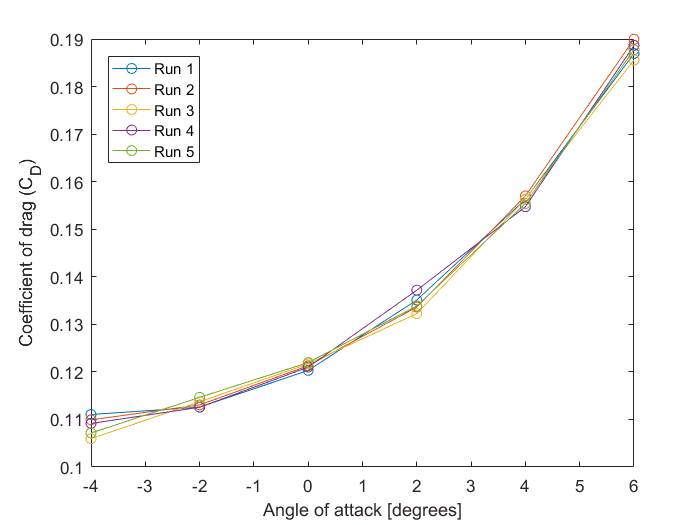

plot(alpha,CD,'o-')
xlabel('Angle of attack [degrees]')
ylabel('Coefficient of drag (C_D)')
legend('Run 1','Run 2','Run 3','Run 4','Run 5','Location','NorthWest')